BL.AI.U4AID25064

S.Sudarshan Rao

% i used "std" as a variable to reprsent the varianve of data

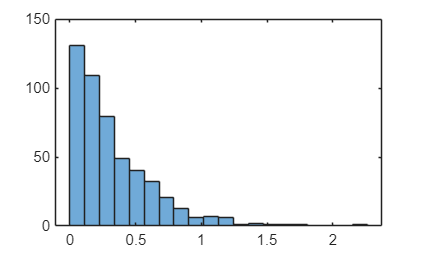

% example problem

y = rand(500,1);
lambda = 3;
x = (-1/lambda)*log(y);
histogram(x,20);

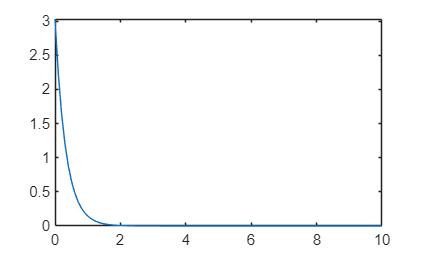


clf;clc;
x = 0:0.1:10;
mean = 0.33;
f = exppdf(x,mean);
plot(x,f)

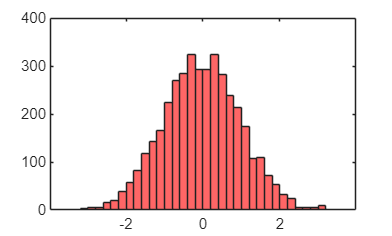

% question -1
u1 = rand(2000,1);
u2 = rand(2000,1);

r = -2*log(u1);
theta = 2*pi*u2;

x1 = (sqrt(r)).*cos(theta);
x2 = (sqrt(r)).*sin(theta);

x = [x1 x2];

histogram(x,'FaceColor','red');

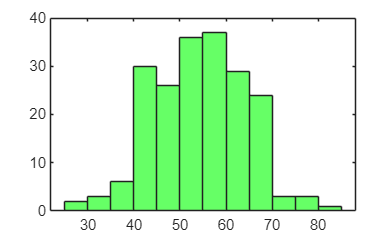

% question - 2

mean = 55;
std = 10;

u1 = rand(100,1);
u2 = rand(100,1);

r = -2*log(u1);
theta = 2*pi*u2;
x1 = mean + std*(sqrt(r)).*cos(theta);
x2 = mean + std*(sqrt(r)).*sin(theta);
x = [x1 x2];
histogram(x,'FaceColor','green');

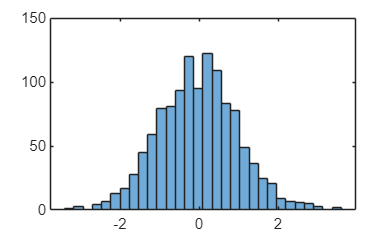

% question - 3
clc;
clf;
clear all;
%(a)
y = randn(1200,1);
histogram(y,30);

%(b)
a = mean(y)

a = -0.0188

b = var(y)

b = 1.0113

% comparing them 
pop_mean = 0;
pop_variance = 1;
c = abs(a  - pop_mean);
d = abs(b - pop_variance);
disp("mean value: "+c);

mean value: 0.018823


disp("variance value: "+d);

variance value: 0.011274


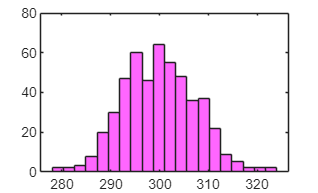

% question - 4 
clear all;
clc;
mu = 300;
sigma = sqrt(50);
y = randn(500,1);
x = mu+sigma*y;
%(a)
histogram(x,20,'FaceColor','magenta');

%(b)
a = mean(x)

a = 300.0402

b = var(x)

b = 53.9776

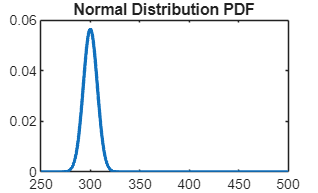

%(c)
z = 250:0.1:500;
pdf = normpdf(z, mu, sigma);
plot(z, pdf, 'LineWidth', 2);
title('Normal Distribution PDF');

% question - 5

% from the third question 
y = randn(1200,1);
a = mean(y)
b = var(y)

og_mean = 0
og_variance = 1

% from the fourth question
og_mu = 300
og_sigma = sqrt(50)
y = randn(500,1);
x = mu+sigma*y;
a = mean(x)
b = var(x)

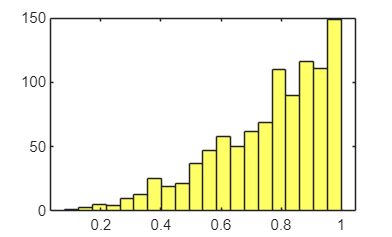

% question - 6
clear all;
clc;
u = rand(1000,1);
x = u.^(1/3);

histogram(x,20,'FaceColor','yellow');

a = mean(x)

a = 0.7605

b = var(x)

b = 0.0354

og_mean = 3/4

og_mean = 0.7500

og_variance = 3/80

og_variance = 0.0375

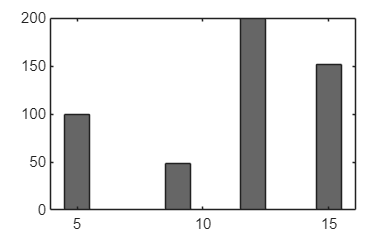

% question - 7
clear all;
clc;
values = [5 9 12 15];
prob = [0.2 0.1 0.4 0.3];
n = 500;
u = rand(n,1);
for i = 1:n
    if u(i) <= 0.2
        x(i) = 5;
    elseif u(i) <= 0.3
        x(i) = 9;
    elseif u(i) <= 0.7
        x(i) = 12;
    else
        x(i) = 15;
    end
end
x = x';
histogram(x,'FaceColor','black');

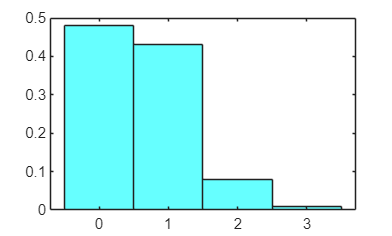

% question - 8
clear all;
clc;
n = 100;      
t = 3;   
p = 0.2;
for i = 1:n
    count = 0;
    for j = 1:t
        u = rand;
        if u <= p
            count = count + 1;
        end
    end
    x(i) = count;
end
x = x';
histogram(x,'Normalization','probability','FaceColor','cyan');

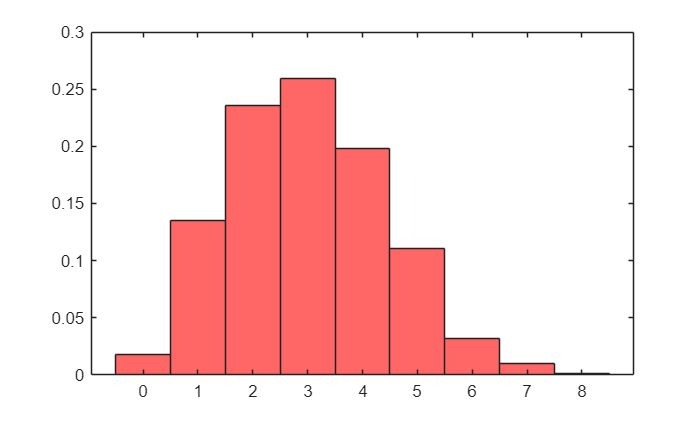

% question - 9
clear all;
clc;
n = 1000;
t = 12;
p = 0.25;
for i = 1:n
    count = 0;
    for j = 1:t
        u = rand;
        if u <= p
            count = count + 1;
        end
    end
    x(i) = count;
end
x = x';
histogram(x,'Normalization','probability','FaceColor','red');

a = mean(x)

a = 3.0010

b = var(x)

b = 2.0551

% population values
og_mean = t*p

og_mean = 3

og_variance = t*p*(1 - p)

og_variance = 2.2500

% question - 10

clear all;
clc;

n = 10000;
count = 0;

for i = 1:n
    x = rand;
    y = rand;
    
    if (x^2 + y^2) <= 1
        count = count + 1;
    end
end

pi_est = 4 * count / n;

disp("Estimated value of pi: " + pi_est);

Estimated value of pi: 3.1136


disp("Actual value of pi: " + pi);

Actual value of pi: 3.1416
